# KalmanFilter

## Practice 1: [Stable System] Estimation of the Position and Uncertainty of a Pendulum in Air

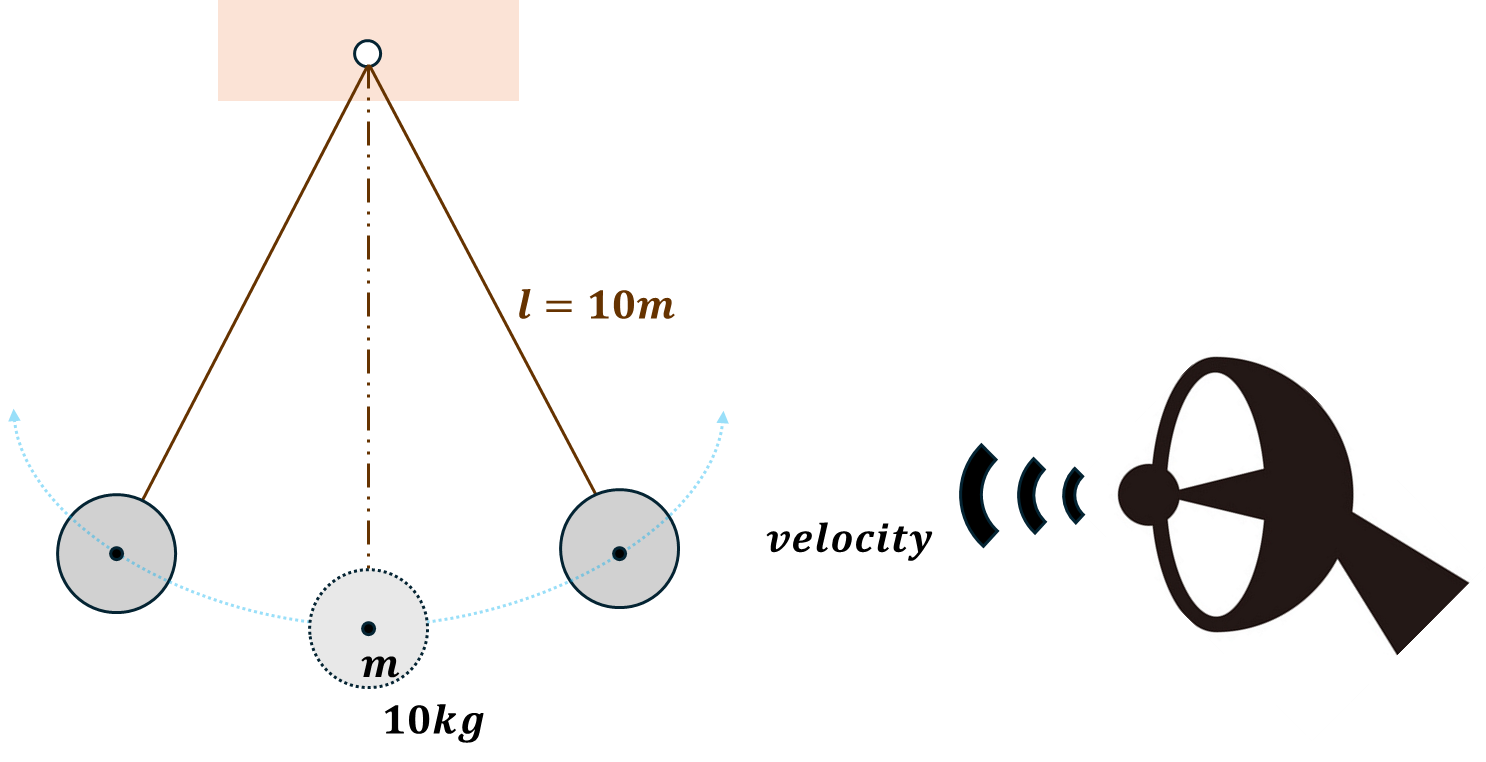

A pendulum is swinging in the air.

Due to air registance, the kinematic energy of the pendulum is being dissipated.

The pendulum has a **mass of 10 kg** and a **string length of 10 meters**.

**Estimate the position and velocity** of pendulum and **its uncertainty** over time.

The **initial position of the pendulum** follows a normal distribution **𝑁(5 deg,3 deg)**,

and the **initial velocity** follows a normal distribution **𝑁(4 deg/s,0.5 deg/s)**.

Assume that the **air resistance force** is proportional to the velocity with some constant damping coefficient, given by **F_air = 20 ⋅ 𝜔**,

and the **gravitational acceleration** is **10 m/s^2**.

(Additionally, assume the angle of the pendulum is sufficiently small

such that nonlinearity with respect to the angle can be ignored.)

We can measure** the velocity of pendulum** with radar system.

The algorithm's uncertainty follows the  a normal distribution with **standard deviation (σ) = 2 m/s**

However there is mistake for set the initial value.

**Actual initial position is 2 deg and initial velocity is 7 deg/s.**

### Motion Equation

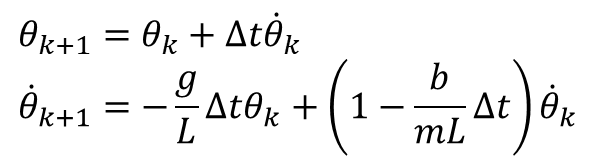

- **m **: mass

- **L **: string length

- **g **: gravitational acceleration

- **b **: damping coefficient

- θ : estimated angle

### Measurement Equation

- : measured velocity

- : estimated velocity

### State space equation modeling

         

- : mean of the state vector x_k+1

- : mean of the state vector x_k

- : system matrix

- : control matrix

- : measurement of time k

- : measurement matrix

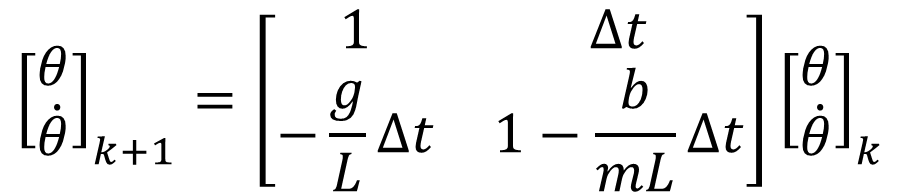

      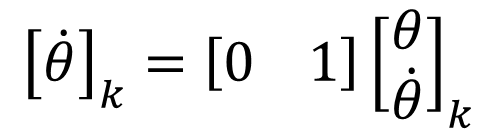

clear; close all;
load("pendulum_meas.mat");
% Set simulation time
total_time = 30;
dt = 0.02;
n_step = total_time / dt;
time = dt:dt:total_time;

% Physics
gravity = 10.0;
pen_length = 10.0;
pen_mass = 10.0;
air_damping = 20.0;

% State space equation modeling
num_of_state = 2;
num_of_measurement = 1;
%%%% TODO %%%%
% F = XXXX;
F = [1 dt; ...
    -gravity/pen_length*dt (1-air_damping/(pen_mass*pen_length)*dt)];
H = [0 1];

% System's Pole
eigen_value = eig(F);
disp("eigen value of system(F): ");

eigen value of system(F): 


disp(eigen_value);

   0.9980 + 0.0199i
   0.9980 - 0.0199i



### Estimate state and uncertainty with Kalman filter

% Initialize state
X_init = [5;
          4];
X_propa = zeros(num_of_state, n_step);
X_propa(:,1) = X_init;
X_kalman_pri = zeros(num_of_state, n_step);
X_kalman_pri(:,1) = X_init;
X_kalman_post = zeros(num_of_state, n_step);
X_kalman_post(:,1) = X_init;


%%%% TODO: Advanced %%%%: Change the initial state uncertainty (P_init)
% Initialize covariance of state
sigma_pose_init = 2.0;
sigma_vel_init = 4;
P_init = [sigma_pose_init^2  0;
          0  sigma_vel_init^2];
P_propa = cell(n_step,1);
P_propa{1} = P_init;
P_kalman_pri = cell(n_step,1);
P_kalman_pri{1} = P_init;
P_kalman_post = cell(n_step,1);
P_kalman_post{1} = P_init;

%%%% TODO: Advanced %%%%: Change the process noise (Q) and measurement noise (R)
% Process noise
sigma_process_pose = 1.0;
sigma_process_vel = 1.0;
Q = [(sigma_process_pose * dt)^2  0;
     0     (sigma_process_vel* dt)^2];
% Measurement noise
sigma_meas_vel = 1.0;
R = sigma_meas_vel^2;

% Estimation
n_skip_update_frame = 10;
for i = 2:n_step

#### Propagation: Time update

    %%%% TODO %%%%: Fill the right equation
    % Propagation: Time update
    % X_propa(:,i) = XXXX; % Just for compare with propagation and kalman filter
    % P_propa{i} = XXXX; % Just for compare with propagation and kalman filter
    % X_kalman_pri(:,i) = XXXX;
    % P_kalman_pri{i} = XXXX;
    X_propa(:,i) = F*X_propa(:,i-1);
    P_propa{i} = F*P_propa{i-1}*F'+Q;
    X_kalman_pri(:,i) = F*X_kalman_post(:,i-1);
    P_kalman_pri{i} = F*P_kalman_post{i-1}*F'+Q;

#### Correction: Measurement update

    if (rem(i, n_skip_update_frame) == 0) % limite update rate
        %%%% TODO %%%%: Fill the right equation
        % Correction: Measurement update (measurement: meas_radar_vel)
        % K = XXXX;
        % X_kalman_post(:,i) = XXXX;
        % P_kalman_post{i} = XXXX;
        K = P_kalman_pri{i}*H'*inv(H*P_kalman_pri{i}*H'+R);
        X_kalman_post(:,i) = X_kalman_pri(:,i)+K*(meas_radar_vel(i)-H*X_kalman_pri(:,i));
        P_kalman_post{i} = (eye(2)-K*H)*P_kalman_pri{i}*(eye(2)-K*H)'+K*R*K';
    else
        % Skip update : Do not edit this section
        X_kalman_post(:,i) = X_kalman_pri(:,i);
        P_kalman_post{i} = P_kalman_pri{i};
    end
end

P_mat = cell2mat(P_propa)';
std_position_x = (P_mat(1, 1:2:end)).^(0.5);
std_velocity_x = (P_mat(2, 2:2:end)).^(0.5);
P_kalman_mat = cell2mat(P_kalman_post)';
std_position_kalman_x = (P_kalman_mat(1, 1:2:end)).^(0.5);
std_velocity_kalman_x = (P_kalman_mat(2, 2:2:end)).^(0.5);

#### Visualization

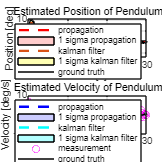

% Visualization
figure('Position', [100, 100, 900, 900]); % 가로 길이를 늘린 크기 설정

% Position plot
subplot(2,1,1);
position_upper_std = X_propa(1,:) + std_position_x;
position_lower_std = X_propa(1,:) - std_position_x;
position_uncertainty_x = [position_upper_std position_lower_std(end:-1:1)];
position_uncertainty_y = [time(1:n_step) time(n_step:-1:1)];
pt_p_u = fill(position_uncertainty_y, position_uncertainty_x, [1 0.8 0.8]);
hold on;

position_upper_kalman_std = X_kalman_post(1, :) + std_position_kalman_x;
position_lower_kalman_std = X_kalman_post(1, :) - std_position_kalman_x;
position_uncertainty_kalman_x = [position_upper_kalman_std position_lower_kalman_std(end:-1:1)];
position_uncertainty_kalman_y = [time(1:n_step) time(n_step:-1:1)];
pt_k_u = fill(position_uncertainty_kalman_y, position_uncertainty_kalman_x, [1.0 1.0 0.7]);

pt_p = plot(time, X_propa(1,:), '--r', "LineWidth",2);
pt_k = plot(time, X_kalman_post(1,:), '--', "LineWidth", 2);
pt_gt = plot(time, actual_pendulum_state(1,:), '-k');
grid on;
xlabel('Time [s]');
ylabel('Position [deg]');
title('Estimated Position of Pendulum');
legend([pt_p, pt_p_u, pt_k, pt_k_u, pt_gt], ["propagation" "1 sigma propagation" "kalman filter" "1 sigma kalman filter" "ground truth"]);

% Velocity plot
subplot(2,1,2);
velocity_upper_std = X_propa(2,:) + std_velocity_x;
velocity_lower_std = X_propa(2,:) - std_velocity_x;
velocity_uncertainty_x = [velocity_upper_std velocity_lower_std(end:-1:1)];
velocity_uncertainty_y = [time(1:n_step) time(n_step:-1:1)];

pt_v_u = fill(velocity_uncertainty_y, velocity_uncertainty_x, [0.8 0.8 1.0]);
hold on;

velocity_upper_kalman_std = X_kalman_post(2,:) + std_velocity_kalman_x;
velocity_lower_kalman_std = X_kalman_post(2,:) - std_velocity_kalman_x;
velocity_uncertainty_kalman_x = [velocity_upper_kalman_std velocity_lower_kalman_std(end:-1:1)];
velocity_uncertainty_kalman_y = [time(1:n_step) time(n_step:-1:1)];
pt_v_k_u = fill(velocity_uncertainty_kalman_y, velocity_uncertainty_kalman_x, [0.7 1.0 1.0]);

pt_v = plot(time, X_propa(2,:), '--b', "LineWidth",2);
pt_v_k = plot(time, X_kalman_post(2,:), '--c', "LineWidth", 2);
pt_v_m = plot(time(n_skip_update_frame:n_skip_update_frame:end), meas_radar_vel(n_skip_update_frame:n_skip_update_frame:end),'om');
pt_gt = plot(time, actual_pendulum_state(2,:), 'k');
grid on;
xlabel('Time [s]');
ylabel('Velocity [deg/s]');
title('Estimated Velocity of Pendulum');
legend([pt_v, pt_v_u, pt_v_k, pt_v_k_u, pt_v_m, pt_gt], ["propagation" "1 sigma propagation" "kalman filter" "1 sigma kalman filter" "measurement" "ground truth"]);

#### Animation

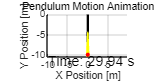

% Animation of the pendulum
figure('Position', [100, 100, 1200, 600]);
axis equal;
hold on;
grid on;
xlabel('X Position [m]');
ylabel('Y Position [m]');
title('Pendulum Motion Animation');

% Calculate pendulum position
theta = deg2rad(X_kalman_post(1, :));
string_length = 10;
pendulum_radius = 0.5;
x_pendulum = string_length * sin(theta);
y_pendulum = -string_length * cos(theta);

% Initialize pendulum line and pendulum circle
pendulum_line = line([0 x_pendulum(1)], [0 y_pendulum(1)], 'Color', 'k', 'LineWidth', 2);

% Initialize uncertainty arc
uncertainty_angle_range = linspace(-1, 1, 100);
uncertainty_arc = plot(0, 0, 'y', 'LineWidth', 40);
set(uncertainty_arc, 'Color', [1, 1, 0, 0.6]);

pendulum_circle = rectangle('Position', [x_pendulum(1) - pendulum_radius, y_pendulum(1) - pendulum_radius, ...
                                          2 * pendulum_radius, 2 * pendulum_radius], ...
                            'Curvature', [1, 1], 'FaceColor', 'r', 'EdgeColor', 'none');

time_text = text(-string_length, -string_length - 1.5, sprintf('Time: %.2f s', time(1)), 'FontSize', 12);


% Animation loop
for k = 2:5:n_step
    set(pendulum_line, 'XData', [0 x_pendulum(k)], 'YData', [0 y_pendulum(k)]);
    set(pendulum_circle, 'Position', [x_pendulum(k) - pendulum_radius, y_pendulum(k) - pendulum_radius, ...
                                      2 * pendulum_radius, 2 * pendulum_radius]);
    angle_uncertainty = std_position_x(k) / string_length; % Angle uncertainty in radians
    uncertainty_arc_x = string_length * sin(theta(k) + angle_uncertainty * uncertainty_angle_range);
    uncertainty_arc_y = string_length * -cos(theta(k) + angle_uncertainty * uncertainty_angle_range);
    set(uncertainty_arc, 'XData', uncertainty_arc_x, 'YData', uncertainty_arc_y);

    set(time_text, 'String', sprintf('Time: %.2f s', time(k)));

    drawnow;
    pause(0.02);
end


## Practice 2: [Unstable System] Estimation of the Position and Uncertainty of Vehicle with CA Motion

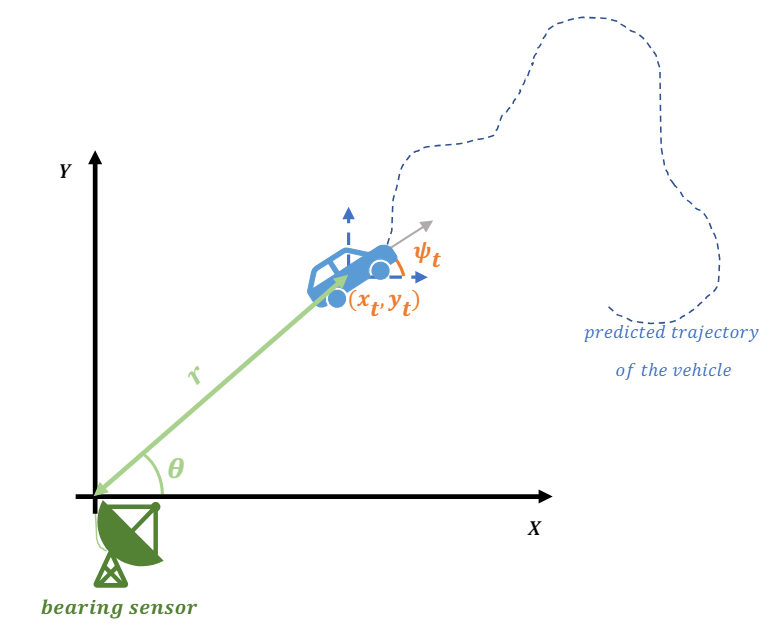

A vehicle is moving on a 2D plane. The initial conditions for the vehicle's state are given as follows:

- **Initial position 𝑥** follows a normal distribution **𝑁(0 m,1 m).**

- **Initial position 𝑦** follows a normal distribution **𝑁(0 m,1 m).**

- **Initial velocity 𝑣𝑥** follows a normal distribution **𝑁(4 m/s,1 m/s).**

- **Initial velocity 𝑣𝑦** follows a normal distribution **𝑁(2 m/s,1 m/s).**

We measure the vehicle's position with GNSS system.

The GNSS measurement are given as follows:

- Position measurement **z **follows a normal distribution ***N([x, y]', diag([1.0^2 1.0^2] m).***

Estimate the motion of the vehicle over time and plot the position and covariance on the 2D plane.

#### Simulation data

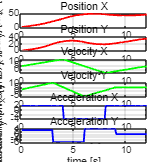

clear; close all;
% Example data for acceleration_x and acceleration_y
dt = 0.1;
total_time = 12;
n_step = total_time / dt;
time = dt:dt:total_time;

% Initial conditions
initial_position_x = 0;
initial_position_y = 0;
initial_velocity_x = 4;
initial_velocity_y = 2;
initial_acceleration_x = 2;
initial_acceleration_y = 3;

% Input generation
acceleration_x = [initial_acceleration_x*ones(1, 4/dt), -4*ones(1, 4/dt), 2*ones(1, 4/dt)];
acceleration_y = [initial_acceleration_y*ones(1, 3/dt), -6*ones(1, 3/dt), 4*ones(1, 3/dt), 0*ones(1, 3/dt)];
input = [acceleration_x;...
         acceleration_y];

% Integrate acceleration to get velocity and position
velocity_x = cumtrapz(time, acceleration_x) + initial_velocity_x;
velocity_y = cumtrapz(time, acceleration_y) + initial_velocity_y;
position_x = cumtrapz(time, velocity_x) + initial_position_x;
position_y = cumtrapz(time, velocity_y) + initial_position_y;

gnss_measurement_noise_sigma = 1.0;
gnss_measurement_update_interval = 6;
gnss_measurement = normrnd([position_x; position_y], gnss_measurement_noise_sigma * ones(size([position_x; position_y])));

% Plot the data
figure('Position', [100, 100, 900, 900]); % 가로 길이를 늘린 크기 설정

% Plot the position data
subplot(6, 1, 1);
plot(time, position_x, 'LineWidth', 1.5, 'Color', "r");
xlabel('time [s]');
ylabel('position_x [m]');
title('Position X');
grid on;

subplot(6, 1, 2);
plot(time, position_y, 'LineWidth', 1.5, 'Color', "r");
xlabel('time [s]');
ylabel('position_y [m]');
title('Position Y');
grid on;

% Plot the velocity data
subplot(6, 1, 3);
plot(time, velocity_x, 'LineWidth', 1.5, 'Color', "g");
xlabel('time [s]');
ylabel('velocity_x [m/s]');
title('Velocity X');
grid on;

subplot(6, 1, 4);
plot(time, velocity_y, 'LineWidth', 1.5, 'Color', "g");
xlabel('time [s]');
ylabel('velocity_y [m/s]');
title('Velocity Y');
grid on;

% Plot the acceleration data
subplot(6, 1, 5);
plot(time, acceleration_x, 'LineWidth', 1.5, 'Color', "b");
xlabel('time [s]');
ylabel('acceleration_x [m/s^2]');
title('Acceleration X');

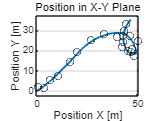

grid on;

subplot(6, 1, 6);
plot(time, acceleration_y, 'LineWidth', 1.5, 'Color', "b");
xlabel('time [s]');
ylabel('acceleration_y [m/s^2]');
title('Acceleration Y');
grid on;


% Plot the trajectory in x-y plane
figure;

plot(position_x, position_y, 'LineWidth', 1.5);
hold on;
plot(gnss_measurement(1, 1:gnss_measurement_update_interval:end), gnss_measurement(2, 1:gnss_measurement_update_interval:end), 'ok');
xlabel('Position X [m]');
ylabel('Position Y [m]');
title('Position in X-Y Plane');
grid on;
axis equal;

#### Motion Equation

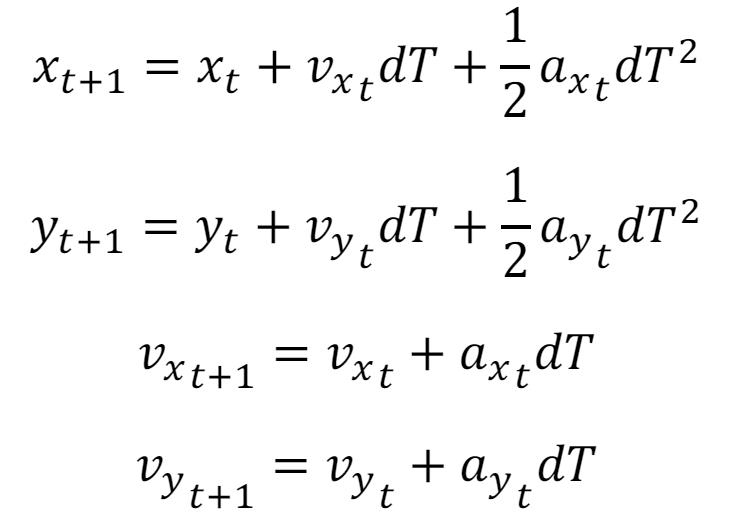

- x_t , y_t : vehicle's X and Y **position** at t

- v_x_t, v_y_t : vehicle's X and Y **velocity** at t

- a_x_t, a_y_t: vehicle's X and Y **acceleration** **input** at t

- dT: **sampling time**

**Measurement Equation**

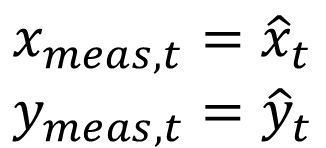

- : estimated position x at t

- : estimated position y at t

- : position measurement at t

- : positoin measurement at t

### State space equation modeling

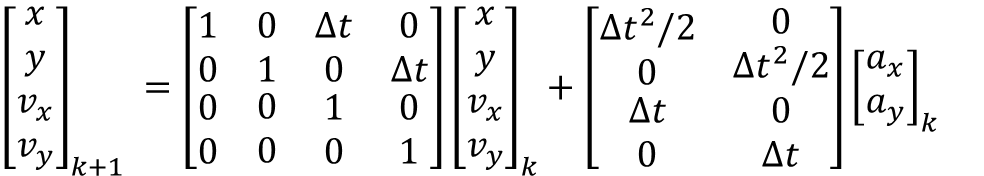

      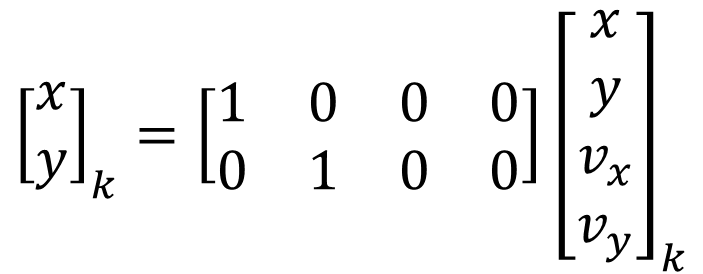

num_of_state = 4; % x, y, vx, vy
num_of_input = 2; % ax, ay
num_of_measurement_order = 2; % x, y

% State space equation modeling
%%%% TODO %%%%
% F = XXXX;
% G = XXXX;
% H = XXXX;
F = [1 0 dt 0;
    0 1 0 dt;
    0 0 1 0;
    0 0 0 1];
G = [        dt^2/2         0; ...
             0         dt^2/2; ...
             dt         0; ...
             0         dt];
H = [1 0 0 0; ...
     0 1 0 0];

% System's Pole
eigen_value = eig(F);
disp("eigen value of system(F): ");

eigen value of system(F): 


disp(eigen_value);

     1
     1
     1
     1



### Estiate state and unceratinty with Kalman Filter

% Initialization state
X_init = [initial_position_x;
          initial_position_y;
          initial_velocity_x;
          initial_velocity_y];
X_propa = zeros(num_of_state, n_step);
X_propa(:,1) = X_init;
X_kalman_pri = zeros(num_of_state, n_step);
X_kalman_pri(:,1) = X_init;
X_kalman_post = zeros(num_of_state, n_step);
X_kalman_post(:,1) = X_init;

% Initialize uncertainty
P_init = [1 0 0 0; ...
         0 1 0 0; ...
         0 0 1 0; ...
         0 0 0 1];
P_propa = cell(n_step,1);
P_propa{1} = P_init;
P_kalman_pri = cell(n_step,1);
P_kalman_pri{1} = P_init;
P_kalman_post = cell(n_step,1);
P_kalman_post{1} = P_init;

%%%% TODO: Advanced %%%%: Change the process noise and measurement noise
% Determine the process and measruement noise
Q_pose = (1.0*dt)^2;
Q_vel = (1.0*dt)^2;
Q = diag([Q_pose, Q_pose, Q_vel, Q_vel]);
R_pose = 1.0^2;
R = diag([R_pose, R_pose]);

% Estimation
for i = 2:n_step

#### Propagation: Time update

    %%%% TODO %%%%: Fill the right equation
    % X_propa(:,i) = XXXX; % Just for compare with propagation and kalman filter
    % P_propa{i} = XXXX; % Just for compare with propagation and kalman filter
    % X_kalman_pri(:,i) = XXXX;
    % P_kalman_pri{i} = XXXX;
    X_propa(:,i) = F*X_propa(:,i-1)+G*input(:,i);
    P_propa{i} = F*P_propa{i-1}*F'+Q;
    X_kalman_pri(:,i) = F*X_kalman_post(:,i-1)+G*input(:,i);
    P_kalman_pri{i} = F*P_kalman_post{i-1}*F'+Q;

#### Correction: Measurement update

    if (rem(i, gnss_measurement_update_interval) == 0) % limite update rate
        %%%% TODO %%%%: Fill the right equation
        % Correction: Measurement update (measurement: meas_radar_vel)
        % K = XXXX;
        % X_kalman_post(:,i) = XXXX;
        % P_kalman_post{i} = XXXX;
        K = P_kalman_pri{i}*H'*inv(H*P_kalman_pri{i}*H'+R);
        X_kalman_post(:,i) = X_kalman_pri(:,i)+K*(gnss_measurement(:,i)-H*X_kalman_pri(:,i));
        P_kalman_post{i} = (eye(4)-K*H)*P_kalman_pri{i}*(eye(4)-K*H)'+K*R*K';
    else
        % Skip update: Don't edit this section
        X_kalman_post(:,i) = X_kalman_pri(:,i);
        P_kalman_post{i} = P_kalman_pri{i};
    end
end

P_mat = cell2mat(P_propa)';
std_position_x = (P_mat(1, 1:num_of_state:end)).^(0.5);
std_velocity_x = (P_mat(3, 3:num_of_state:end)).^(0.5);
std_position_y = (P_mat(2, 2:num_of_state:end)).^(0.5);
std_velocity_y = (P_mat(4, 4:num_of_state:end)).^(0.5);

P_kalman_mat = cell2mat(P_kalman_post)';
std_position_kalman_x = (P_kalman_mat(1, 1:num_of_state:end)).^(0.5);
std_velocity_kalman_x = (P_kalman_mat(3, 3:num_of_state:end)).^(0.5);
std_position_kalman_y = (P_kalman_mat(2, 2:num_of_state:end)).^(0.5);
std_velocity_kalman_y = (P_kalman_mat(4, 4:num_of_state:end)).^(0.5);

#### Visualization

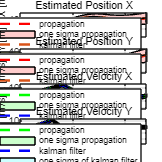

% Visualization for X and Y
figure('Position', [100, 100, 900, 900]);

% Position plot for X
subplot(4,1,1);
position_upper_std_x = X_propa(1,:) + std_position_x;
position_lower_std_x = X_propa(1,:) - std_position_x;
position_uncertainty_x = [position_upper_std_x position_lower_std_x(end:-1:1)];
position_uncertainty_time_x = [time(1:n_step) time(n_step:-1:1)];
pt_p_u_x = fill(position_uncertainty_time_x, position_uncertainty_x, [1 0.8 0.8]);
hold on;

p_kalman_upper_std_x = X_kalman_post(1, :) + std_position_kalman_x;
p_kalman_lower_std_x = X_kalman_post(1, :) - std_position_kalman_x;
p_kalman_uncertainty_x = [p_kalman_upper_std_x p_kalman_lower_std_x(end:-1:1)];
p_kalman_uncertainty_time_x = [time(1:n_step) time(n_step:-1:1)];
pt_p_k_u_x = fill(p_kalman_uncertainty_time_x, p_kalman_uncertainty_x, [1 1 0.7]);

pt_p_x = plot(time, X_propa(1,:), '--r', "LineWidth",2);
pt_p_k_x = plot(time, X_kalman_post(1,:), '--', "LineWidth", 2);
pt_p_gt_x = plot(time, position_x, '-k');
grid on;
xlabel('Time [s]');
ylabel('Position X [m]');
title('Estimated Position X');
legend([pt_p_x, pt_p_u_x, pt_p_k_x, pt_p_k_u_x, pt_p_gt_x], ["propagation" "one sigma propagation" "kalman filter" "one sigma of kalman filter" "ground truth"]);

% Position plot for Y
subplot(4,1,2);
position_upper_std_y = X_propa(2,:) + std_position_y;
position_lower_std_y = X_propa(2,:) - std_position_y;
position_uncertainty_y = [position_upper_std_y position_lower_std_y(end:-1:1)];
position_uncertainty_time_y = [time(1:n_step) time(n_step:-1:1)];
pt_p_u_y = fill(position_uncertainty_time_y, position_uncertainty_y, [1 0.8 0.8]);
hold on;

p_kalman_upper_std_y = X_kalman_post(2, :) + std_position_kalman_y;
p_kalman_lower_std_y = X_kalman_post(2, :) - std_position_kalman_y;
p_kalman_uncertainty_y = [p_kalman_upper_std_y p_kalman_lower_std_y(end:-1:1)];
p_kalman_uncertainty_time_y = [time(1:n_step) time(n_step:-1:1)];
pt_p_k_u_y = fill(p_kalman_uncertainty_time_y, p_kalman_uncertainty_y, [1 1 0.7]);

pt_p_y = plot(time, X_propa(2,:), '--r', "LineWidth",2);
pt_p_k_y = plot(time, X_kalman_post(2,:), '--', "LineWidth", 2);
pt_p_gt_y = plot(time, position_y, '-k');
grid on;
xlabel('Time [s]');
ylabel('Position Y [m]');
title('Estimated Position Y');
legend([pt_p_y, pt_p_u_y, pt_p_k_y, pt_p_k_u_y, pt_p_gt_y], ["propagation" "one sigma propagation" "kalman filter" "one sigma of kalman filter" "ground truth"]);

% Velocity plot for X
subplot(4,1,3);
velocity_upper_std_x = X_propa(3,:) + std_velocity_x;
velocity_lower_std_x = X_propa(3,:) - std_velocity_x;
velocity_uncertainty_x = [velocity_upper_std_x velocity_lower_std_x(end:-1:1)];
velocity_uncertainty_time_x = [time(1:n_step) time(n_step:-1:1)];
pt_v_u_x = fill(velocity_uncertainty_time_x, velocity_uncertainty_x, [0.8 1.0 0.8]);
hold on;

velocity_k_upper_std_x = X_kalman_post(3,:) + std_velocity_kalman_x;
velocity_k_lower_std_x = X_kalman_post(3,:) - std_velocity_kalman_x;
velocity_uncertainty_x = [velocity_k_upper_std_x velocity_k_lower_std_x(end:-1:1)];
velocity_k_uncertainty_time_x = [time(1:n_step) time(n_step:-1:1)];
pt_v_k_u_x = fill(velocity_k_uncertainty_time_x, velocity_uncertainty_x, [0.8 1.0 1.0]);

pt_v_x = plot(time, X_propa(3,:), '--g', "LineWidth",2);
pt_v_k_x = plot(time, X_kalman_post(3,:), '-- b', "LineWidth", 2);
pt_v_gt_x = plot(time, velocity_x, '-k');
grid on;
xlabel('Time [s]');
ylabel('Velocity X [m/s]');
title('Estimated Velocity X');
legend([pt_v_x, pt_v_u_x, pt_v_k_x, pt_v_k_u_x, pt_v_gt_x], ["propagation" "one sigma propagation" "kalman filter" "one sigma of kalman filter" "ground truth"]);

% Velocity plot for Y
subplot(4,1,4);
velocity_upper_std_y = X_propa(4,:) + std_velocity_y;
velocity_lower_std_y = X_propa(4,:) - std_velocity_y;
velocity_uncertainty_y = [velocity_upper_std_y velocity_lower_std_y(end:-1:1)];

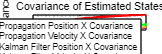

velocity_uncertainty_time_y = [time(1:n_step) time(n_step:-1:1)];
pt_v_u_y = fill(velocity_uncertainty_time_y, velocity_uncertainty_y, [0.8 1.0 0.8]);
hold on;

velocity_k_upper_std_y = X_kalman_post(4,:) + std_velocity_kalman_y;
velocity_k_lower_std_y = X_kalman_post(4,:) - std_velocity_kalman_y;
velocity_uncertainty_y = [velocity_k_upper_std_y velocity_k_lower_std_y(end:-1:1)];
velocity_k_uncertainty_time_y = [time(1:n_step) time(n_step:-1:1)];
pt_v_k_u_y = fill(velocity_k_uncertainty_time_y, velocity_uncertainty_y, [0.8 1.0 1.0]);

pt_v_y = plot(time, X_propa(4,:), '--g', "LineWidth",2);
pt_v_k_y = plot(time, X_kalman_post(4,:), '-- b', "LineWidth", 2);
pt_v_gt_y = plot(time, velocity_y, '-k');

grid on;
xlabel('Time [s]');
ylabel('Velocity Y [m/s]');
title('Estimated Velocity Y');
legend([pt_v_y, pt_v_u_y, pt_v_k_y, pt_v_k_u_y, pt_v_gt_y], ["propagation" "one sigma propagation" "kalman filter" "one sigma of kalman filter" "ground truth"]);

% Covariance plot for position, velocity, and acceleration
figure('Position', [100, 100, 900, 300]);
semilogy(time, std_position_x.^2, 'r', 'LineWidth', 2);
hold on;
semilogy(time, std_velocity_x.^2, 'g', 'LineWidth', 2);
semilogy(time, std_position_kalman_x.^2, '-', 'LineWidth', 2);
semilogy(time, std_velocity_kalman_x.^2, '-', 'LineWidth', 2);
grid on;
xlabel('Time [s]');
ylabel('Covariance');
title('Covariance of Estimated States');
legend("Propagation Position X Covariance", "Propagation Velocity X Covariance", "Kalman Filter Position X Covariance", "Kalman Filter Velocity X Covariance");

#### Animation

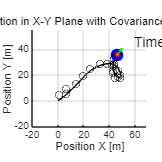

% X-Y plane position plot with covariance (1 sigma)
figure('Position', [100, 100, 900, 900]);
hold on;

h_ellipse = plot_covariance_ellipse([X_kalman_post(1,1); X_kalman_post(2,1)], P_kalman_post{1}(1:2, 1:2), 'r', 'yellow');
h_trajectory = plot(X_kalman_post(1,1), X_kalman_post(2,1), 'b--', "LineWidth", 2); % past trajectory
h_traj_gt = plot(position_x(1), position_y(1), '-k');
h_position = plot(position_x(1), X_kalman_post(2,1), 'bo', 'MarkerSize', 10, 'MarkerFaceColor', 'b');
h_velocity = quiver(X_kalman_post(1,1), X_kalman_post(2,1), X_kalman_post(3,1), X_kalman_post(4,1), 'g', 'LineWidth', 2, 'MaxHeadSize', 2); % velocity arrow
h_gnss_meas = plot(gnss_measurement(1,1), gnss_measurement(2,1), 'ok');
time_text = text(max(X_kalman_post(1,:)) + 10, max(X_kalman_post(2,:)) + 10, sprintf('Time: %.2f s', time(1)), 'FontSize', 12);

xlabel('Position X [m]');
ylabel('Position Y [m]');
title('Position in X-Y Plane with Covariance Ellipse');
grid on;
axis equal;
xlim([min(position_x) - 20, max(position_x) + 20]);
ylim([min(position_y) - 20, max(position_y) + 20]);


for i = 1:n_step
    delete(h_ellipse);

    h_ellipse = plot_covariance_ellipse([X_kalman_post(1,i); X_kalman_post(2,i)], P_kalman_post{i}(1:2, 1:2), 'r', 'yellow');
    set(h_trajectory, 'XData', X_kalman_post(1,i), 'YData', X_kalman_post(2,i));
    set(h_traj_gt, 'XData', position_x(:), 'YData', position_y(:));
    set(h_position, 'XData', X_kalman_post(1,i), 'YData', X_kalman_post(2,i));
    set(h_velocity, 'XData', X_kalman_post(1,i), 'YData', X_kalman_post(2,i), 'UData', X_kalman_post(3,i), 'VData', X_kalman_post(4,i));
    set(h_gnss_meas, 'XData', gnss_measurement(1, gnss_measurement_update_interval:gnss_measurement_update_interval:i), 'YData', gnss_measurement(2, gnss_measurement_update_interval:gnss_measurement_update_interval:i));
    
    set(time_text, 'String', sprintf('Time: %.2f s', time(i)));
    
    drawnow;
    pause(0.01);
end

% Function to plot covariance ellipse

function h = plot_covariance_ellipse(mu, cov_matrix, edge_color, fill_color)
    [eigvec, eigval] = eig(cov_matrix);
    chisquare_val = 2.2789; % Corresponds to 1-sigma for 2 DOF
    theta_grid = linspace(0, 2*pi);
    phi = atan2(eigvec(2,1), eigvec(1,1));
    X0 = mu(1);
    Y0 = mu(2);
    a = chisquare_val*sqrt(eigval(1,1));
    b = chisquare_val*sqrt(eigval(2,2));
    ellipse_x_r  = a*cos(theta_grid);
    ellipse_y_r  = b*sin(theta_grid);
    R = [cos(phi) sin(phi); -sin(phi) cos(phi)];
    r_ellipse = [ellipse_x_r; ellipse_y_r]' * R;
    h = fill(r_ellipse(:,1) + X0, r_ellipse(:,2) + Y0, fill_color, 'EdgeColor', edge_color, 'FaceAlpha', 0.5);
end
